# ME5554/AOE5754/ECE5754 Applied Linear Systems - Final Project

Samuel Kramer

11/20/2023

Due: 12/08/2023

% --Setup system
    clear; clc; format compact; close all; warning off;

    % --Comment out if not on Ubuntu Machine:
    cd("/home/samkramer/Desktop/Engineering/Course Work/ME 5554 -- Applied Linear Systems/ME 5554 -- Final Project")

% --Define max control inputs from previous project
    u1_max = 1959.957;
    u2_max = 1941.943;

## Problem 1 [2 pts].  Prepare the Open-Loop Plant

*The state-space LTI object you developed in the Midterm Project for the open-loop plant should have been saved in a  .mat file.  Before you work on the Final Project, you are responsible for correcting any errors you had in your open-loop plant!  You are NOT allowed to regenerate the open-loop LTI state-space plant in this LiveScript!!!  The open-loop plant MUST be loaded from a .mat file.*

* After loading the .mat file, display the open-loop numerical state-space model.  This model MUST display appropriately chosen statenames, inputnames (ok to use defaults here), and outputnames.*

*Next, extract the Aol, Bol, Col, and Dol matrices, but do not display these results (because you already displayed them in the previous step).*

*Compute the open-loop eigenvalues (ol_poles), and the system dimensions (N, M, P).  Assign these quantities to variables for use later in the LiveScript, but do not display them here.*

% --Load in data
    cd("..")
    cd("ME 5554 -- Midterm Project")
    load("State_Space_System.mat")
    cd("..")
    cd("ME 5554 -- Final Project/")
    sys_ol = sys

sys_ol =
 
  A = 
                  x_dot      y_dot  theta_dot          x          y      theta
   x_dot             -1          0          0          0          0      -9.81
   y_dot              0         -3          0          0          0          0
   theta_dot          0          0       -1.6          0          0          0
   x                  1          0          0          0          0          0
   y                  0          1          0          0          0          0
   theta              0          0          1          0          0          0
 
  B = 
              Right Thrust  Left Thruste
   x_dot                 0             0
   y_dot               0.1           0.1
   theta_dot        0.1302        0.0898
   x                     0             0
   y                     0             0
   theta                 0             0
 
  C = 
              x_dot      y_dot  theta_dot          x          y      theta
   x              0          0          0        

% --Declare Open Loop Plant Model
    A = sys.A; B = sys.B; C = sys.C; D = sys.D;

% --Compute OL poles and the system dimensions M,N,P
    ol_poles = flip(sort(eig(A)));          % Open Loop Poles (greatest to least)
    N = length(A);                          % N states
    M = width(B);                           % M inputs
    P = height(C);                          % P outputs

## Problem 2 [5 pts].  Simulate Closed-Loop Control

*You are given the following set of desired closed-loop poles which are known to result in 5% settling times (transient times) that are less than 3 seconds without saturating any of the control signals.*

cl_poles = [
    -29 + 15i
    -29 - 15i
    -32 + 0i
    -1.6 + 0.76i
    -1.6 - 0.76i
    -1.2 + 0i];

*Use the *`PLACE`* function to compute the full state feedback control gain matrix, and display your result.*

% --Place poles and define G
    G = place(A, B, cl_poles)

G = 1.0e+04 *

   -1.1141   -0.0683    0.2142   -1.5589   -0.1439    5.3811
    1.3482    0.0988   -0.2457    1.8892    0.1952   -6.4921


% --Redefine System
        Acl = A - B*G;

        C = [0 0 0 1 0 0;
             0 0 0 0 1 0;
             0 0 0 0 0 1];
        D = [0 0;
             0 0;
             0 0]; 

        C = C - D*G;
        Ccl = [C;
            -G];

        sys_cl = ss(Acl,[],Ccl,[]);

% --Define state space system names
    sys_cl.StateName = ["x_dot";
                     "y_dot";
                     "theta_dot";
                     "x";
                     "y";
                     "theta"];
    sys_cl.OutputName = ["x"; "y"; "theta";"u1";"u2"];
    sys_cl

sys_cl =
 
  A = 
                  x_dot      y_dot  theta_dot          x          y      theta
   x_dot             -1          0          0          0          0      -9.81
   y_dot         -234.1     -33.57      31.51     -330.3     -51.28       1111
   theta_dot      239.8     0.1374     -59.83      333.2       12.1      -1176
   x                  1          0          0          0          0          0
   y                  0          1          0          0          0          0
   theta              0          0          1          0          0          0
 
  B = 
     Empty matrix: 6-by-0
 
  C = 
               x_dot       y_dot   theta_dot           x           y       theta
   x               0           0           0           1           0           0
   y               0           0           0           0           1           0
   theta           0           0           0           0           0           1
   u1      1.114e+04       682.8       -2142   1.559e+04     

% --Check that the poles are correct
    flip(sort(eig(Acl)))

ans =  -29.0000 +15.0000i
 -29.0000 -15.0000i
 -32.0000 + 0.0000i
  -1.6000 + 0.7600i
  -1.6000 - 0.7600i
  -1.2000 + 0.0000i


*Assume that the actual plant starts with the following initial conditions (NOTE:  These are NEW IC's!!!):*

% --Define initial conditions
    x0 = -2;            % meters
    x0dot = 0.5;        % meters/sec
    y0 = 1;             % meters
    y0dot = 0;          % meters/sec
    theta0 = -0.5;      % radians
    theta0dot = 0.1;    % radians/sec

    initials = [x0dot;
                y0dot;
                theta0dot;
                x0;
                y0;
                theta0];

*Assume that you have access to the full state vector, then construct a closed-loop state-space LTI object using the feedback gains from above.  You must augment the output equation to output the original outputs as well as the control signals.  Simulate the initial value response using *`INITIAL`*.  Choose a final simulation time of 4 seconds for this simulation.  Estimate the 5% settling times for each output.  Generate a plot like what was required for the Midterm Project with the three outputs on the left-hand side (separate axes for each output), and the control signals on the right-hand side of the figure (separate axes for each control signal).  Annotate each plot with some kind of marker for the 5% settling times, the min and max allowable control signals, grid lines, axis labels, and units.*

% --Simulate Response of Design
    [y,t] = initial(sys_cl, initials, 5);

% --Plotting the outputs new response
    figure()
    subplot(3,2,1)
    plot(t, y(:,1))
        hold on
        grid on
        xlim([0 4])
        ylabel("x (m)")

    subplot(3,2,3)
    plot(t, y(:,2))
        hold on
        grid on
        xlim([0 4])
        ylabel("y (m)")

    subplot(3,2,5)
    plot(t, y(:,3))
        hold on
        grid on
        xlim([0 4])
        xlabel('Time (s)')
        ylabel("\theta (rad)")

    subplot(2,2,2)
    plot(t, y(:,4))
        hold on
        grid on
        xlim([0 4])
        ylabel("u_1 (N)")
        yline(u1_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u1_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u1_max-200 u1_max+200])

    subplot(2,2,4)
    plot(t, y(:,5))
        hold on
        grid on
        xlim([0 4])
        str = "Closed Loop Response";
        sgtitle(str)
        xlabel("Time (s)")
        ylabel("u_2 (N)")
        yline(u2_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u2_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u2_max-200 u2_max+200])
        
% --Finding the settling times
    xx = lsiminfo(y(:,1),t);     % X values
    yy = lsiminfo(y(:,2),t);
    tt = lsiminfo(y(:,3),t);
    uu1 = lsiminfo(y(:,4),t);
    uu2 = lsiminfo(y(:,5),t);

% --Making Table of values
    yy_settling_idx = min(find(abs(y(:,2)) <= 0.05));
    yy_settling_time = t(yy_settling_idx); 
    settling_times = [xx.TransientTime;
                      yy_settling_time;
                      tt.TransientTime;
                      uu1.TransientTime;
                      uu2.TransientTime];
    var_names = {'X';'Y';'Theta';'U1';'U2'};
    T = table(settling_times,VariableNames="Settling Times (s)",RowNames = var_names);
    display(T)

T = 5×1 table
             Settling Times (s)
             __________________
    X               2.6849     
    Y               2.7231     
    Theta           2.5685     
    U1            0.074982     
    U2            0.076809     

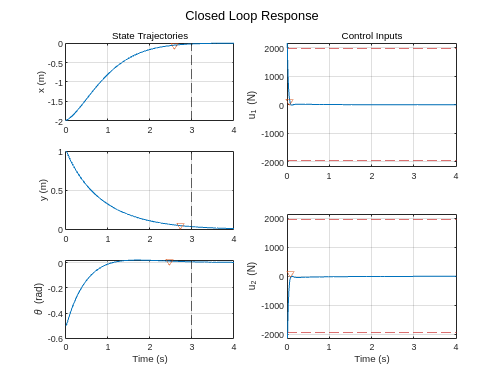

% --Plotting onto subplots
    idx = find(abs(t - xx.TransientTime) < 0.1);
    idx = min(idx);
    subplot(3,2,1)
    plot(t(idx),y(idx,1),'V')
    xline(3,'--')
    subtitle('State Trajectories')

    subplot(3,2,3)
    plot(yy_settling_time, y(yy_settling_idx,2),'V')
    xline(3,'--')

    idx = find(abs(t - tt.TransientTime) < 0.1);
    idx = min(idx);
    subplot(3,2,5)
    plot(t(idx),y(idx,3),'V')
    xline(3,'--')

    idx = find(abs(t - uu1.TransientTime) < 0.01);
    idx = min(idx);
    subplot(2,2,2)
    plot(t(idx), y(idx,4),'V')
    subtitle('Control Inputs')

    idx = find(abs(t - uu2.TransientTime) < 0.01);
    idx = min(idx);
    subplot(2,2,4)
    plot(t(idx), y(idx, 4), 'V')

*Include the animation plot in the LiveScript as documentation of the performance.*

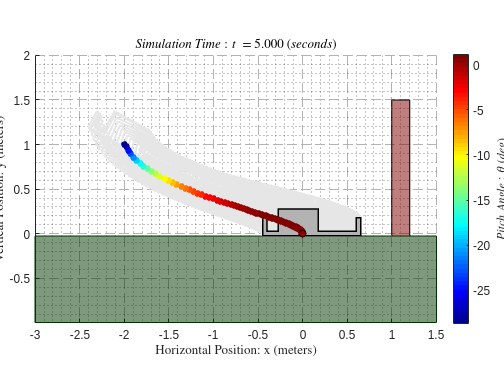

% --Setup Animation
    t_vector = 0:0.1:3;
    x_vector = linspace(x0,0,length(t_vector));
    y_vector = linspace(y0,0,length(t_vector));
    theta_vector = linspace(theta0,0,length(t_vector));

% --Animate
    als_f23_animate(t, y(:,1), y(:,2), y(:,3))

## Problem 3 [2 pts].   Evaluate Observability

*First show that this system is completely observable using all three outputs.  Then determine whether this system is completely observable using any subset of outputs.  Justify your answers.*

% --Determine observability of full system
    O = ctrb(A',C');
    rank(O)

ans = 6

    rank(O) == N

ans = logical
   1

Therefore, with all three outputs we have a fully observable system because the rank of the observer matrix O is equal to the number of states N in our system (6).

% --Determine observability with only one of the outputs available
    sset = nchoosek(1:P,1);
    for i = 1:P

        % --Changing Ccl matrices
            Ccl_subset = [C(sset(i),:)];
            fprintf("New closed loop C output matrix will look like: \n")
            disp(Ccl_subset)

        % --Testing controlability
            O = ctrb(A', Ccl_subset');
            fullrank = length(A) - rank(O);

        % --Output solutions
            if fullrank == 0
                fprintf("\n \nThe system is completely observable with only output %1.0f. \n", i)

            else
                fprintf("The system is not completely observable with only output %1.0f. \n", i)
            end
            fprintf("Rank of observability martix is %1.0f",rank(O))
            fprintf("\n \n \n")

    end

New closed loop C output matrix will look like: 


     0     0     0     1     0     0


The system is not completely observable with only output 1. 


Rank of observability martix is 4

New closed loop C output matrix will look like: 


     0     0     0     0     1     0


The system is not completely observable with only output 2. 


Rank of observability martix is 2

New closed loop C output matrix will look like: 


     0     0     0     0     0     1


The system is not completely observable with only output 3. 


Rank of observability martix is 2

Therefore with only any of the three outputs available we do not have an observable system because the rank of the observability matrix O is not equivalent to the number of states N in our system (6). 

% --Determine Observability with only 2 outputs
    sset = nchoosek(1:P,2);
    for i = 1:P

        % --Changing Ccl matrices
            Ccl_subset = [C(sset(i,1),:); C(sset(i,2),:)];
            fprintf("New closed loop C output matrix will look like: \n")
            disp(Ccl_subset)

        % --Testing controlability
            O = ctrb(Acl', Ccl_subset');
            fullrank = length(A) - rank(O);

        % --Output solutions
            if fullrank == 0
                fprintf("\n \nThe system is completely observable with only outputs %1.0f and %1.0f. \n", sset(i,1), sset(i,2))

            else
                fprintf("The system is not completely observable with only output %1.0f. \n", i)
            end
            fprintf("Rank of observability martix is %1.0f",rank(O))
            fprintf("\n \n \n")

    end

New closed loop C output matrix will look like: 


     0     0     0     1     0     0
     0     0     0     0     1     0



 
The system is completely observable with only outputs 1 and 2. 


Rank of observability martix is 6

New closed loop C output matrix will look like: 


     0     0     0     1     0     0
     0     0     0     0     0     1



 
The system is completely observable with only outputs 1 and 3. 


Rank of observability martix is 6

New closed loop C output matrix will look like: 


     0     0     0     0     1     0
     0     0     0     0     0     1



 
The system is completely observable with only outputs 2 and 3. 


Rank of observability martix is 6

Our system is fully observable with any combination of only two of the sensor outputs in our system because the rank of the observability matrices in any of the systems is equivalent to the number of states in our system (6).

## Problem 4 [3 pts].  Design a Full-Order Luenberger Observer

*In this problem, you will compute the gains for a state estimator using all three outputs. You must first choose appropriate pole locations for the state estimator (observer), and then compute and display the associated feedback gain matrix using the *`PLACE`* function.*

For this problem we are trying to determine the optimal pole locations for the dynamic state estimator system. To do this we want to drive the derivative of the error to 0.


$$\dot{e(t)} = [A - KC] e(t)$$


Where our poles are at the given locations:


$$[sI - A^T + KC^T] = 0$$


Classical control theory says that we need the pole locations to be to the left of the controller poles from the $A - BG$ matrix to converge properly to the desired values.

% --Choose ideal pole locations for the state estimator
    observer_poles = [-10 + 5i;
                      -10 - 5i;
                      -7;
                      -2 + 0.76i;
                      -2 - 0.76i;
                      -1.3 + 0i];
    
% --Derive observer gain matrix K 
    K = place(A', C', observer_poles)'

K =     1.8000         0   -9.8100
         0   -1.5543   15.5060
         0   -2.7669    4.4591
    7.3000         0         0
         0   11.1298   -6.4489
         0    3.1924    8.2702


*To document your design, you must generate a plot that includes the open-loop poles from Problem 1, the closed-loop poles from Problem 2, and observer poles from this problem.  Use common markers for each set of poles (i.e. all open-loop poles must use the same marker, etc.) so that it is easy to distinguish the poles on the figure.  Include a legend that only has three entries in it (open-loop, closed-loop, observer), corresponding to the three sets of poles.  You must use the *`SGRID`* function (read the Matlab help!!) to generate appropriate grid lines.  Annotate your plot with axis labels.  Make sure your legend does not cover up any of the poles!*

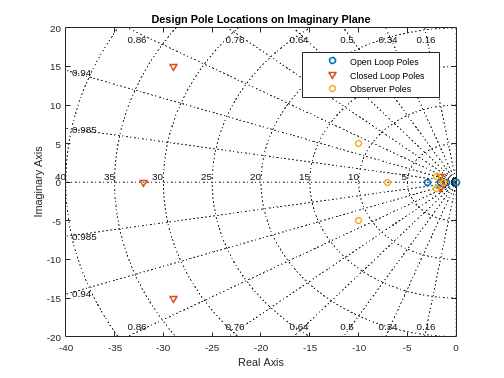

% --Creating OL Pole plot
    figure()
    plt1 = plot(real(ol_poles), imag(ol_poles), 'o', "LineWidth", 1.75);
        hold on
        xlabel('Real Axis')
        ylabel('Imaginary Axis')
        title("Design Pole Locations on Imaginary Plane")
        xlim([-40 0])
        ylim([-20 20])

    plot(real(cl_poles), imag(cl_poles), "V", "LineWidth", 1.5)

    plot(real(observer_poles), imag(observer_poles), "o", "LineWidth", 1.5)
        legend("Open Loop Poles", "Closed Loop Poles", "Observer Poles", "Autoupdate","off", "Position", [0.59944,0.74328,0.27143,0.11905])
        sgrid

## Problem 5 [10 pts].  Simulate Output Feedback Control

*For this problem, you must simulate the complete output feedback control system, which will include the state estimator and full state feedback using the estimated states. In order to insure that the estimated states *$\hat{\mathbf{x}}$* (and outputs *$\hat{\mathbf{y}}$*) have converged before control is enabled, you will first need to generate an augmented LTI closed-loop output-feedback control model with the state feedback gain *$\mathbf{G}$* set to zero (it is easier to just use *$\left(0*\mathbf{G}\right)$* in the matrices).  This first LTI object will be used for the first ****200 milliseconds**** of the response.  You must use the same initial states on the plant as defined in Problem 2 above, but the initial observer states must be zero.  Your closed-loop state-space output equation must also be augmented to output the following three vectors:  *$\mathbf{y}$*, *$\hat{\mathbf{y}}$*, and *$\mathbf{u}$*.*

For this we are going to be doing the initial no-control section of our simulation where we want to allow our estimator error to converge to zero. This means that our t_max will be set to 0.2 seconds and we will have to set our system to have a feedback control of 0. From here we can generate the state equation with the Luenberger observer implemented below for our open loop system. 

State equation:

$\left\lbrack \begin{array}{c}
\dot{x} \\
\hat{\dot{x} } 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
A & 0\\
\textrm{KC} & \hat{A} -K\hat{C} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{c}
B\\
\hat{B} +K\left(D-\hat{D} \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
u\\
u
\end{array}\right\rbrack$

But this is open loop and we want a closed loop system, we can then substitute in our control law $u(t) = -G\hat{x}$ we get the following

$\left\lbrack \begin{array}{c}
\dot{x} \\
\hat{\dot{x} } 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
A & -\textrm{BG}\\
\textrm{KC} & \hat{A} -K\hat{C} -\textrm{BG}-K\left(D-\hat{D} \right)G
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$

[12x1] = [12x12][12x1]

I think that because we are in simulation world, the state and output equations for our system A and our simulation $\hat{A}$ are going to be the same. Our values for $D$ and $\hat{D}$ are going to cancel out because we have both set as 0 because there is no direct passthrough in our system. Our output equations then become the following:

$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
C & -\textrm{DG}\\
0 & \hat{C} -\hat{D} G
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$

And inputting our $u(t) = -G\hat{x}$ into the C matrix we then get the following equations:


$$\left\lbrack \begin{array}{c}
y\\
\hat{y} \\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
C & -\textrm{DG}\\
0 & \hat{C} -\hat{D} G\\
0 & -G
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$$


[8x1] = [8x12][12x1]

% --Initial Observer Values
    O_0 = zeros(6,1);
    G_0 = 0.*G;
    initials_of = [initials;
                   O_0];

% --Setup the following system
    Aof = [A, -B*G_0;
           K*C, A - K*C - B*G_0 - K*(D-D)*G_0];         % Which yields a 12x12 matrix
    Cof = [C, -D*G_0;
           zeros(3,6), C-D*G_0;
           zeros(2,6), -G_0];                           % Which is a 8x12 Matrix

    sys_of_c_off = ss(Aof, [], Cof, []); 

*Next, you must generate a second augmented LTI closed-loop output-feedback control model that is identical to the first model except that the state-feedback control gains are not zero, i.e. the controller is enabled.  This second LTI object will be used for the remainder of the simulation.*

% --Setup the following system
    Aof = [A, -B*G;
           K*C, A - K*C - B*G - K*(D-D)*G];             % Which yields a 12x12 matrix
    Cof = [C, -D*G;
           zeros(3,6), C-D*G;
           zeros(2,6), -G];                             % Which is a 8x12 Matrix

    sys_of_c_on = ss(Aof, [], Cof, []); 

% --Finding the eigenvalues of the system
    eig_vals_of = eig(Aof);
    disp(eig_vals_of)

 -29.0000 +15.0000i
 -29.0000 -15.0000i
 -32.0000 + 0.0000i
  -7.0000 + 0.0000i
  -1.2000 + 0.0000i
  -1.3000 + 0.0000i
  -1.6000 + 0.7600i
  -1.6000 - 0.7600i
 -10.0000 + 5.0000i
 -10.0000 - 5.0000i
  -2.0000 + 0.7600i
  -2.0000 - 0.7600i


*You are now ready to simulate the closed-loop response, but it must happen in two separate simulation stages.  In the first stage, you will use the INITIAL function to simulate for 200 milliseconds.  At the end of this first simulation stage, you must capture the final state vector and use it as the initial state vector for the second simulation stage.  The total simulation duration should be 4 seconds like above.*

In order to calculate the states we must first simulate the system and then select the last values from the first 6 states. Then we must calculate the derivatives using the times histories of our system. We must do this by taking the time step from the system, which is output as $t(end) - t(end - 1)$ and then we can divide the values by this time step. This will give us the new values for the states $x_1, x_2, x_3$. 

% --Fist simulation using the initial values
    [y_1, t_1] = initial(sys_of_c_off, initials_of, 0.200);

% --Initial state vector recapture
    initials_of_2 = [initials(1:3);
                   y_1(end,1:3)';
                   zeros(3,1);
                   y_1(end,4:6)'];

% --Initial Value Simulation
    [y_2, t_2] = initial(sys_of_c_on, initials_of_2, 5);

% --Plutting them together
    y = [y_1; y_2];
    t = [t_1; t_2 + 0.2032];
    t_of = t;
    y_of = y;

*Generate the standard annotated plot (three output subplots on the left and two control signal subplots on the right), with appropriate annotations; but you must also plot the estimated output signals on top of the associated actual output signals.  It must be clear from your plots that the estimated outputs all start from zero and converge to the actual outputs within 200 milliseconds.  Do NOT try to get the observer states to converge too fast because it will be difficult to see the convergence on the plots.  If you have done this step correctly, you should see 5% settling times that are comparable to the original design from Problem 2.  The 5% settling times on the outputs must all be below 3 seconds, and you must not saturate either of the control signals.*

*In addition to the normal five subplot figure, you must also include the animation plot in the LiveScript as documentation of the performance.*

% --Plotting the outputs new response
    figure()
    subplot(3,2,1)
    plot(t, y(:,1))
        hold on
        grid on
        xlim([0 4])
        ylabel("x (m)")
    plot(t,y(:,4), '--')
    legend("Actual State","Estimated State","Autoupdate","off", location="southeast")

    subplot(3,2,3)
    plot(t, y(:,2))
        hold on
        grid on
        xlim([0 4])
        ylabel("y (m)")
    plot(t,y(:,5), '--')
    legend("Actual State","Estimated State","Autoupdate","off", location="northeast")

    subplot(3,2,5)
    plot(t, y(:,3))
        hold on
        grid on
        xlim([0 4])
        xlabel('Time (s)')
        ylabel("\theta (rad)")
    plot(t,y(:,6), '--')
    legend("Actual State","Estimated State","Autoupdate","off", location="southeast")

    subplot(2,2,2)
    plot(t, y(:,7))
        hold on
        grid on
        xlim([0 4])
        ylabel("u_1 (N)")
        yline(u1_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u1_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u1_max-200 u1_max+200])

    subplot(2,2,4)
    plot(t, y(:,8))
        hold on
        grid on
        xlim([0 4])
        str = "Closed Loop Response";
        sgtitle(str)
        xlabel("Time (s)") 
        ylabel("u_2 (N)")
        yline(u2_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u2_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u2_max-200 u2_max+200])


% --Compute the 5% settling times
    xx = lsiminfo(y(:,1),t);     % X values
    yy = lsiminfo(y(:,2),t);
    tt = lsiminfo(y(:,3),t);
    uu1 = lsiminfo(y(:,4),t);
    uu2 = lsiminfo(y(:,5),t);

% --Calculating the ones that don't make sense on the lsiminfo command
    xx_settling_idx = find( abs( y(:,1) ) <= 0.05*abs(initials(4,1)), 1);
    xx_settling_time = t(xx_settling_idx);
    
    yy_settling_idx = find(abs(y(:,2)) <= 0.05*abs(initials(5,1)), 1);
    yy_settling_time = t(yy_settling_idx);

    tt_settling_idx = find(abs(y(:,3)) <= 0.05*abs(initials(6,1)), 1);
    tt_settling_time = t(tt_settling_idx);

% --Making Table of values 
    settling_times = [xx_settling_time;
                      yy_settling_time;
                      tt_settling_time;
                      uu1.TransientTime;
                      uu2.TransientTime];
    var_names = {'X';'Y';'Theta';'U1';'U2'};
    T = table(settling_times,VariableNames="Settling Times (s)",RowNames = var_names);
    display(T)

T = 5×1 table
             Settling Times (s)
             __________________
    X              1.8987      
    Y              2.6874      
    Theta          1.0207      
    U1             3.3882      
    U2             3.3056      

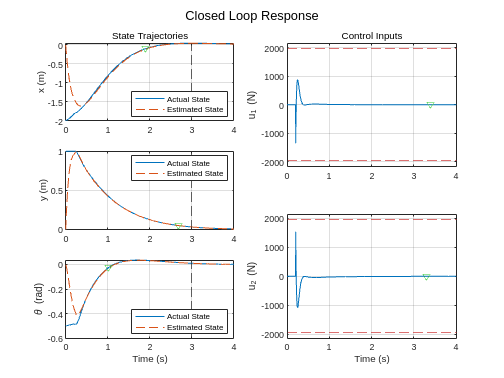

% --Plotting onto subplots/home/samkramer/Desktop/Engineering/Course Work/ME 5554 -- Applied Linear Systems/ME 5554 -- Final Project/Kramer_ME5554_FInal_Project.mlx
    subplot(3,2,1)
    plot(t(xx_settling_idx),y(xx_settling_idx,1),'V', 'Color', [0.2 0.8 0.2])
    xline(3,'--')
    subtitle('State Trajectories')

    subplot(3,2,3)
    plot(yy_settling_time, y(yy_settling_idx,2),'V', 'Color', [0.2 0.8 0.2])
    xline(3,'--')

    subplot(3,2,5)
    plot(t(tt_settling_idx),y(tt_settling_idx,3),'V', 'Color', [0.2 0.8 0.2])
    xline(3,'--')

    idx = find(abs(t - uu1.TransientTime) < 0.01);
    idx = min(idx);
    subplot(2,2,2)
    plot(t(idx), y(idx,4),'V', 'Color', [0.2 0.8 0.2])
    subtitle('Control Inputs')

    idx = find(abs(t - uu2.TransientTime) < 0.01, 1);
    subplot(2,2,4)
    plot(t(idx), y(idx, 4), 'V', 'Color', [0.2 0.8 0.2])

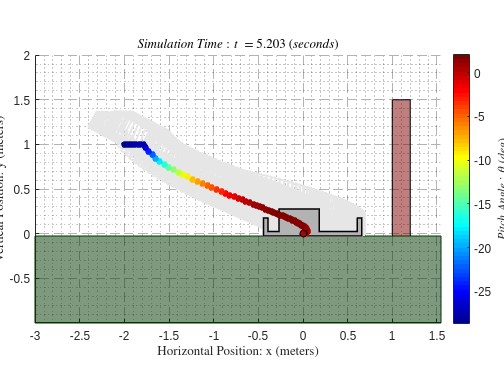

% --Animate response
    als_f23_animate(t, y(:,1), y(:,2), y(:,3))

This design converges well and allows the system to be controlled well and does not saturate the actuators. The convergence of the estimator does occur after the system has started the control inputs (after 200ms) but still meets the required time responses for the system. The control inputs spike when the control gets put in and then begin to settle out a few milliseconds after. I did need to manually calculate the settling times for some because the transient time calculation from the matlab function did not yield a realistic settling time that if used to analyze the system, it would not sufficiently meet design requirements. 

### For problems 6, 7, and 8, you will design and simulate another Output Feedback Controller (i.e. a state estimator with full state feedback control), but now you must also include Integral Control for reference tracking as defined in the notes.  

### This closed-loop simulation will require you to redesign the state-feedback control gains $\mathbf{G}$ (you cannot use the gains from Problem 2!); however, you should plan to use the same state estimator gains $\mathbf{K}$you designed in Problem 4.  You are welcome to redesign the state estimater gains (poles), but this is not recommended because it will add unnecessary time to your project completion.

### You must expect to iterate on problems 6, 7, and 8 until you achieve one acceptable design.

## Problem 6 [10 pts].  Design an LQI compensator

*You must use LQR optimal control to design the state-feedback gains for this simulation.  The MathWorks has provided a separate tool called *`LQI`* for computing the state-feedback gains when you are implementing state feedback with integral control.  Note that *`LQI`* is identical to *`LQR`* except that *`LQI`* already knows that you are designing for reference tracking with an integral controller.  You can NOT use *`LQR`* for this design, and you must use *`LQI!`*  You must also use the LTI object for the open-loop system as input to the *`LQI`* function.  Read the online help for *`LQI`* before starting this problem!*

*First define the LQI cost function weighting matrices *$\mathbf{Q}$* and *$\mathbf{R}$*.  Note that *`LQI`* also accepts a weighting matrix *$\mathbf{N}$*, which allows cross-weighting between states and controls, but you should NOT use this weighting matrix for this problem!  Make sure you understand the dimensions of each of these weighting matrices.*

% --Define weighting matrices
    Q_gains = [25; 3001; 2003; 
               21; 13; 21; 
               200; 205; 209];
    Q_weight = 2;
    R_gains = [1; 1];

    Q = Q_weight .* diag(Q_gains);
    R = diag(R_gains);

% --Find LQI compensator function
    [G_lqi, S, e] = lqi(sys_ol, Q, R);

*Generate and display the optimal control gains and separate them into *${\mathbf{G}}_0$* and *${\mathbf{G}}_I$* matrices.*

After solving the Riccati equation, the outputs to our system are the two gain matrices contained in G. $G = -[G_0, G_i]$ where we have $G_0$ = [2x6] and $G_i$ = [2x3], which allows us to say that


$$u(t) = -G_0\hat{x}(t) - G_I\hat{x}(t) = -[G_0, G_I]$$

$$\left\lbrack \begin{array}{c}
\hat{x} \\
x_I 
\end{array}\right\rbrack$$


% --Outputting the Gains
    G_0 = G_lqi(:,1:6)

G_0 =   -26.3942   -5.6275   81.9688  -42.2657  -35.8572  224.3997
  -10.7828   47.6907   15.5835  -18.1245   72.6445   58.4777


    G_i = G_lqi(:,7:9)

G_i =    18.1034    8.6067   -0.0000
    8.5011  -18.3283    0.0000


% --Compare with old G gains without reference input control
    varnames = {'Integral Gains','Original Gains'};
    t = table(G_0', G','VariableNames',varnames);
    display(t)

t = 6×2 table
      Integral Gains        Original Gains  
    __________________    __________________
    -26.394    -10.783     -11141      13482
    -5.6275     47.691    -682.82     988.49
     81.969     15.584     2141.7    -2456.8
    -42.266    -18.124     -15589      18892
    -35.857     72.644    -1439.3     1952.1
      224.4     58.478      53811     -64921

## Problem 7 [15 pts].  Construct the OFC with Reference Inputs

*Generate an augmented state-space system for the closed-loop Output Feedback Controller (state feedback with estimated states) and Reference Tracking.  Your complete closed-loop state-space model must have:*

- *State vector consisting of:  *$\mathbf{x}$*, *$\hat{\mathbf{x}}$*, and *${\mathbf{x}}_I$

- *Output vector consisting of:  *$\mathbf{y}$*, *$\hat{\mathit{\mathbf{y}}}$*, and *$\mathbf{u}$

- *Input vector consisting of:  *$\mathbf{r}$

- *State Feedback Control law:  *$u=-\left\lbrack \begin{array}{cc}
{\mathbf{G}}_0  & {\mathbf{G}}_I 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{\mathbf{x}} \\
{\mathbf{x}}_I 
\end{array}\right\rbrack$

After generating the closed-loop output feedback control state-space model, compute and display the closed-loop eigenvalues.

To generate the math for the Output Feedback Controller with the Reference Inputs:

        
$$\dot{x} = Ax + Bu$$


        
$$y = Cx + Du$$


Then augment it to have our integral control into our state and output equations

       
$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x_I } 
\end{array}\right\rbrack =A\left\lbrack \begin{array}{c}
x\\
x_I 
\end{array}\right\rbrack +B\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\\

\end{array}\right\rbrack r$$


       
$$\left\lbrack \begin{array}{c}
y\\
y_I 
\end{array}\right\rbrack =C\left\lbrack \begin{array}{c}
x\\
x_I 
\end{array}\right\rbrack +D\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\\

\end{array}\right\rbrack r$$


The state equation can then be given as the following assuming that we have the following control law that $u = [-G_0 -G_I]$$\left\lbrack \begin{array}{c}
\hat{x} \\
x_I 
\end{array}\right\rbrack$:


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } \\
\dot{x_I } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A & -{\textrm{BG}}_0  & -{\textrm{BG}}_I \\
\textrm{KC} & \hat{A} -K\hat{C} -{\hat{B} G}_0 -K\left(D-\hat{D} \right)G_0  & -{\hat{B} G}_I -K\left(D-\hat{D} \right)G_I \\
-C & {\textrm{DG}}_0  & {\textrm{DG}}_I 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
I
\end{array}\right\rbrack r$$


[15x1] = [15x15][15x1] + [15x3][3x1]

We can then find the expression for the output equation by applying the same control law:


$$\left\lbrack \begin{array}{c}
y\\
y_I 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
C & 0 & 0\\
0 & \hat{C}  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
D\\
\hat{D} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r$$



$$\left\lbrack \begin{array}{c}
y\\
y_I 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
C & 0 & 0\\
0 & \hat{C}  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
D\\
\hat{D} 
\end{array}\right\rbrack \left\lbrack 0\;\;\;-G_0 \;\;\;-G_I \right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r$$


[6x1] = [6x15][15x1] + [6x2][2x15][15x1] + [6x3][3x1]


$$\left\lbrack \begin{array}{c}
y\\
y_I 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
C & 0 & 0\\
0 & \hat{C}  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & -{\textrm{DG}}_0  & -{\textrm{DG}}_I \\
0 & -\hat{D} G_0  & -\hat{D} G_I 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r$$


[6x1] = [6x15][15x1] + [6x15][15x1]+ [6x3][3x1]

Implementing our control law that $u = -Gx$ into our system we get that:


$$\left\lbrack \begin{array}{c}
y\\
y_I \\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
C & -{\textrm{DG}}_0  & -{\textrm{DG}}_I \\
0 & C-\hat{D} G_0  & -\hat{{\textrm{DG}}_I } \\
0 & -G_0  & -G_I 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} \\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
I\\
0
\end{array}\right\rbrack r$$


[8x1] = [8x15][15x1]+[8x3][3x1]

Which when we look at our equations we then get that we have the following augmented equations which are as follows:


$$\dot{x} = A_{aug}x + B_{aug}r$$



$$y = C_{aug}x + D_{aug}r$$


Where our vectors for x are augmented to include the integral control y contains $y, y_I, u$ as outputs from our simulation.

% --Ensure we are using the plant definitions of the A, B, C, and D
    A = sys_ol.A;
    B = sys_ol.B;
    C = sys_ol.C;
    D = sys_ol.D;

% --Define our new ss system with integral control
    A_ofci = [A, -B*G_0, -B*G_i,;
             K*C, A-K*C-B*G_0 - K*(D-D)*G_0, -B*G_i - K*(D-D)*G_i;
             -C, D*G_0, D*G_i];                                       
    B_ofci = [zeros(6,3);
              zeros(6,3);
              eye(3)];                                                 
    C_ofci = [C,          -D*G_0,   -D*G_i;                                    
              zeros(3,6),  C-D*G_0, -D*G_i;
              zeros(2,6), -G_0,     -G_i];                             
    D_ofci = [eye(3);
              eye(3);
              zeros(2,3)];                                              

% --Define COF ss system
    sys_ofci = ss(A_ofci, B_ofci, C_ofci, D_ofci);
    set(sys_ofci, "outputname",{'x','y','theta','x_hat','y_hat','theta_hat','u1','u2'})
    set(sys_ofci, "statename",{'x_dot','y_dot','theta_dot','x','y','theta','x_d_h','y_d_h','t_d_h','x_hat','y_hat','theta_hat','x_I','y_I','theta_I'})
    set(sys_ofci, "inputname",{'x_ref','y_ref','theta_ref'})
    sys_ofci

sys_ofci =
 
  A = 
                   x_dot       y_dot   theta_dot           x           y       theta       x_d_h       y_d_h       t_d_h       x_hat       y_hat   theta_hat         x_I         y_I     theta_I
   x_dot              -1           0           0           0           0       -9.81           0           0           0           0           0           0           0           0           0
   y_dot               0          -3           0           0           0           0       3.718      -4.206      -9.755       6.039      -3.679      -28.29       -2.66      0.9722   -6.44e-08
   theta_dot           0           0        -1.6           0           0           0       4.405       -3.55      -12.07       7.131      -1.855      -34.47       -3.12      0.5253  -2.717e-08
   x                   1           0           0           0           0           0           0           0           0           0           0           0           0           0           0
   y           

% --Display CL Eigenvalues
    CL_eigenvals = flip(sort(eig(A_ofci)));
    disp(CL_eigenvals)

 -14.9859 + 0.0000i
 -10.0000 + 5.0000i
 -10.0000 - 5.0000i
  -7.0000 + 0.0000i
  -2.7028 + 0.0000i
  -2.0000 + 0.7600i
  -2.0000 - 0.7600i
  -1.2535 + 0.4971i
  -1.2535 - 0.4971i
  -1.3000 + 0.0000i
  -0.5731 + 1.0889i
  -0.5731 - 1.0889i
  -0.2681 + 0.2684i
  -0.2681 - 0.2684i
   0.0000 + 0.0000i


## Problem 8 [10 pts].  Simulate the Output Feedbaceye(3)k Controller with Reference Inputs

*For this problem, you will simulate the closed-loop response of your control system using *`LSIM()`*; however, you must first generate a suitable reference profile as an input.  Before you can generate a reference profile, you need to understand the initial position and the final desired position of the drone.  These are new initial conditions, and a very different final position from any closed-loop simulation you have done before.*

***Initial Plant Conditions:****  The plant (drone) must start with the following initial states:*

    $x\left(0\right)=-2$* m, *$y\left(0\right)=1$* m, and *$\theta \left(0\right)=0$* rad.*

    $\dot{x} \left(0\right)=0$* m/s, *$\dot{y} \left(0\right)=0$* m/s, and *$\dot{\theta} \left(0\right)=0$* rad/s.*

***Initial Observer Conditions:****  You may assume that the initial observer states are identical to the initial plant states.*

***Final Plant Conditions:****  The plant (drone) must reach the following final states:*

    $x\left(0\right)=+2$* m, *$y\left(0\right)=0$* m, and *$\theta \left(0\right)=0$* rad.*

    $\dot{x} \left(0\right)=0$* m/s, *$\dot{y} \left(0\right)=0$* m/s, and *$\dot{\theta} \left(0\right)=0$* rad/s.*

***Evaluation Criteria:***

- *Notice that the final state is on the opposite side of the 1.5m high red wall in the animation!  The drone is NOT allowed to make contact with the wall at any point during the simulation.  *

- *The drone is NOT allowed to make contact with the ground at any point during the simulation except for the final time where the drone must sit on the ground.*

- *The drone must reach the final state by 30 seconds (*$\textrm{tfinal}\le 30s$*).*

- *The control signals *$u_1$* and *$u_2$* must remain within the saturation bounds established in the Midterm Project.*

- *There is NO formal settling time requirement; however, your actual output responses *$\mathbf{y}$* must track the reference responses *$\mathbf{r}$*reasonably accurately.  For example, if your reference profiles have dwell regions, then there should be zero steady-state error after transients have subsided.  If your reference profiles have ramp regions, then you should expect to see a steady-state error during the ramp, which looks like a delayed response.  How closely you track the references will depend on your choice of weighting coefficients in the Q matrix.  Note that a steady-state error during the ramp is perfectly acceptable as long as you choose the reference profile such that the drone does not make contact with the wall!*

- *For this simulation, the observer and the controller must both be enabled at t=0 (i.e. do NOT attempt a two-stage simulation like problem 5.*

- *You MUST use *`LSIM`* to simulate the closed-loop time response*

- *Before constructing the reference profiles, you must first construct a time vector for the simulation.  I recommend choosing a uniform step size of *$\textrm{ts}=0\ldotp 002$* seconds:*


$$t=\textrm{ts}*\left\lbrack 0:\textrm{round}\left(\frac{\textrm{tfinal}}{\left.\textrm{ts}\right)}\right)\right\rbrack$$


- *For each time step in the time vector, you must generate a reference vector for each of the outputs.  You will need to generate a particular path vs. time profile for the desired x and y position; however, I recommend choosing the following reference profile for the angular position:*


$$\theta_{\textrm{ref}} =\textrm{zeros}\left(\textrm{size}\left(t\right)\right)$$


- *You must use the same plot structure as before except that new signals that must be added.  Each of the three output subplots on the left must include the reference profile, the actual output, and the estimated output on the same axis.*

- *I may decide to give bonus points for solutions that meet all of the criteria above and reach the final state in a minimum time (relative to your classmates).*

- *In addition to the normal five subplot figure, you must also include the animation plot in the LiveScript as documentation of the performance*

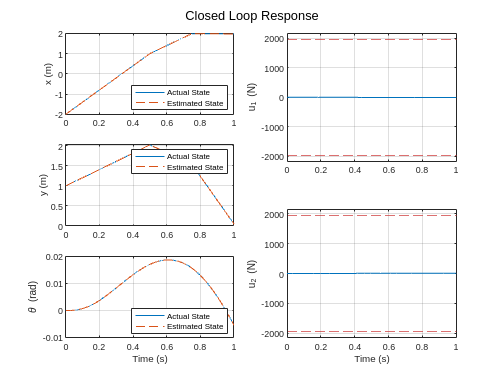

% --Setting up the evaluation criteria
    IC_plant = [0; 0; 0;        % x_dot; y_dot; t_dot
               -2; 1; 0];       % x; y; theta
    IC_observer = [0; 0; 0;     % x_dot; y_dot; t_dot
                  -2; 1; 0];
    FC_plant = [0; 0; 0;
                2; 0; 0];
    ts = 10000;
    x0 = [IC_plant; IC_observer; 0; 0; 0;];

% --Develop the reference path for the drone

    % --Segment 1
        t_1 = 0:1/ts:0.5 - (1/ts);
        x_ref = linspace(-2, 1, length(t_1));
        y_ref = linspace(1, 2, length(t_1));
        t_ref = linspace(0, 0, length(t_1));
    
    % --Segment 2
        t_2 = 0.5:1/ts:0.75 - (1/ts);
        x_ref_2 = linspace(1, 2, length(t_2));
        y_ref_2 = linspace(2, 1.5, length(t_2));
        t_ref_2 = linspace(-0, 0, length(t_2));
    
    % --Segment 3
        t_3 = 0.75:1/ts:1 - (1/ts);
        x_ref_3 = linspace(2, 2, length(t_3));
        y_ref_3 = linspace(1.5, 0, length(t_3));
        t_ref_3 = linspace(0, 0, length(t_3));

% --Collect reference path
    t = [t_1, t_2, t_3];          
    x_ref = [x_ref, x_ref_2, x_ref_3];      
    y_ref = [y_ref, y_ref_2, y_ref_3];         
    t_ref = [t_ref, t_ref_2, t_ref_3]; 

    ref = [x_ref;
           y_ref;
           t_ref];

% --Simulate the responses using lsim
    [y, t] = lsim(sys_ofci, ref, t);

% --Plot outputs and control signals
    figure()
    subplot(3,2,1)
    plot(t, y(:,1))
        hold on
        grid on
        xlim([0 1])
        ylabel("x (m)")
    plot(t,y(:,4), '--')
    legend("Actual State","Estimated State","Autoupdate","off", location="southeast")

    subplot(3,2,3)
    plot(t, y(:,2))
        hold on
        grid on
        xlim([0 1])
        ylabel("y (m)")
    plot(t,y(:,5), '--')
    legend("Actual State","Estimated State","Autoupdate","off", location="northeast")

    subplot(3,2,5)
    plot(t, y(:,3))
        hold on
        grid on
        xlim([0 1])
        xlabel('Time (s)')
        ylabel("\theta (rad)")
    plot(t,y(:,6), '--')
    legend("Actual State","Estimated State","Autoupdate","off", location="southeast")

    subplot(2,2,2)
    plot(t, y(:,7))
        hold on
        grid on
        xlim([0 1])
        ylabel("u_1 (N)")
        yline(u1_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u1_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u1_max-200 u1_max+200])

    subplot(2,2,4)
    plot(t, y(:,8))
        hold on
        grid on
        xlim([0 1])
        str = "Closed Loop Response";
        sgtitle(str)
        xlabel("Time (s)") 
        ylabel("u_2 (N)")
        yline(u2_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u2_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u2_max-200 u2_max+200])

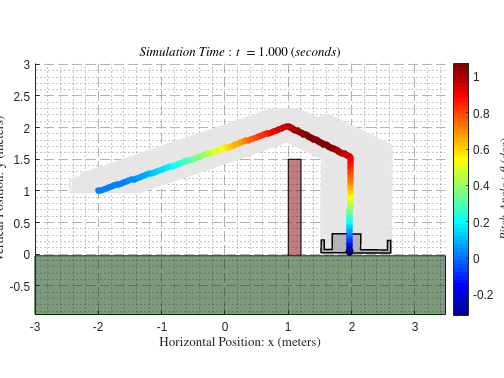

% --Animate the simulation response
    als_f23_animate(t, y(:,1), y(:,2), y(:,3))

In the above simulation I was able to successfully land the drone at the final initial conditions point of (0,2,0) and do so in the time alotted. I will note that the simulation of the control inputs seems to be very strange because they are very small for the system. I did notice that when I was using much higher gains for the LQI controller, like up in the 10^6 range, I was getting much higher and more realistic control inputs, however, the system was unstable and would oscillate around the desired value without converging, or in some cases would flip the drone when trying to descend to the final point. I was able to come up with this controller design which was able to successfully reach the desired final point. I believe that this system does work and the simulation makes sense because I also simulated it backwards to see if it would work and it did. In all I think this design satisfies the requirements for the system needs.  